## Comparing shape of lip and tongue spectral fluorescence across subjects

The keratinized areas of the dorsal surface of the tongue (e.g., filiform papillae) likely absorb less light due to increased reflectance from keratin.

The non-keratinized areas of the lower innner lip oral mucosal tissue absorbs more light than keratinized regions due to less reflectance. The inner lip epithelium is generally thicker than the dorsal tongue epithelium, potentially leading to increased light absorption. The rich vascular network in the lip may contribute to greater absorbance by blood compared to the tongue.

%{
cd /Users/joyce/Github/isetcam; addpath(genpath(pwd));
cd /users/joyce/Github/oraleye/; addpath(genpath(pwd));
cd /users/joyce/Github/isetfluorescence/; addpath(genpath(pwd));
cd /users/joyce/Github/oe_tongue_lip/; addpath(genpath(pwd));
%}

ieInit;
waves = 500:5:700;


nWave = 580 

nWave = 580

yScale = 'linear';
T = oeDatabaseCreate;

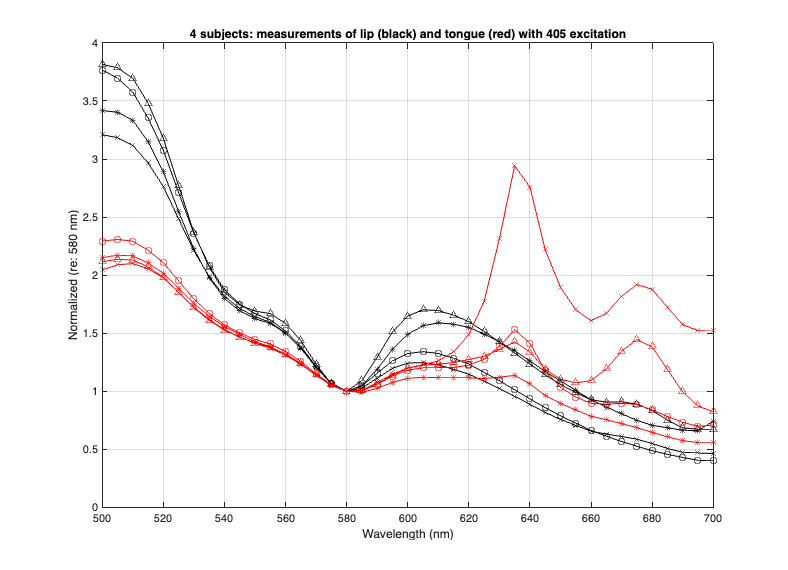

lipFiles405 = ieTableGet(T,'ewave',405,'substrate','lip','elevel',980,'return','files');
data = oeReadFiles(lipFiles405,'waves',waves,'normalized wave',nWave);
symbols = {'kx-','k*-','k^-','ko-'};
ieNewGraphWin;
for ii= 1:numel(lipFiles405)
    plot(waves,data(:,ii),symbols{ii}); hold on; 
    set(gca,'yscale',yScale);
end

tongueFiles405 = ieTableGet(T,'ewave',405,'substrate','tongue','elevel',980,'return','files');
% Collected on the same day as above.
selected = [1,3,4,5];
tongueFiles405 = tongueFiles405(selected);
data = oeReadFiles(tongueFiles405,'waves',waves,'normalized wave',nWave);
symbols = {'rx-','r*-','r^-','ro-'};

for ii= 1:numel(tongueFiles405)
    plot(waves,data(:,ii),symbols{ii}); hold on;
    set(gca,'yscale',yScale);
end
grid on;
xlabel('Wavelength (nm)')
if isempty(nWave), ylabel('Energy (watts/sr/nm/m^2)');
else, ylabel(sprintf('Normalized (re: %d nm)',nWave));
end
title('4 subjects: measurements of lip (black) and tongue (red) with 405 excitation');

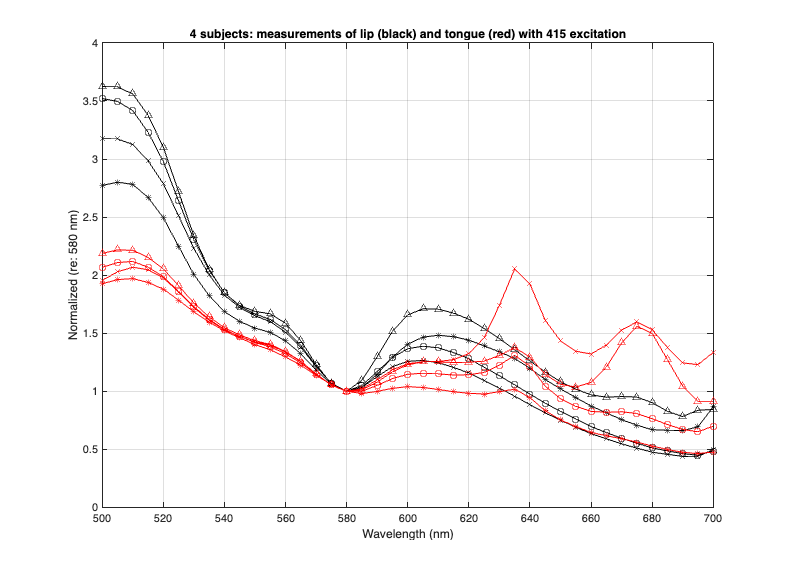

lipFiles415 = ieTableGet(T,'ewave',415,'substrate','lip','elevel',910,'return','files');
symbols = {'kx-','k*-','k^-','ko-'};
% Collected on the same day as above.
selected = [11,12,13,14];
lipFiles415 = lipFiles415(selected);
data = oeReadFiles(lipFiles415,'waves',waves,'normalized wave',nWave);

ieNewGraphWin;
for ii= 1:numel(lipFiles415)
    plot(waves,data(:,ii),symbols{ii}); hold on; 
    set(gca,'yscale',yScale);
end

tongueFiles415 = ieTableGet(T,'ewave',415,'substrate','tongue','elevel',910,'return','files');
tongueFiles415 = tongueFiles415(selected);
data = oeReadFiles(tongueFiles415,'waves',waves,'normalized wave',nWave);
symbols = {'rx-','r*-','r^-','ro-'};

for ii= 1:numel(tongueFiles415)
    plot(waves,data(:,ii),symbols{ii}); hold on; 
    set(gca,'yscale',yScale);
end

grid on;
xlabel('Wavelength (nm)')
if isempty(nWave), ylabel('Energy (watts/sr/nm/m^2)');
else, ylabel(sprintf('Normalized (re: %d nm)',nWave));
end
title('4 subjects: measurements of lip (black) and tongue (red) with 415 excitation');

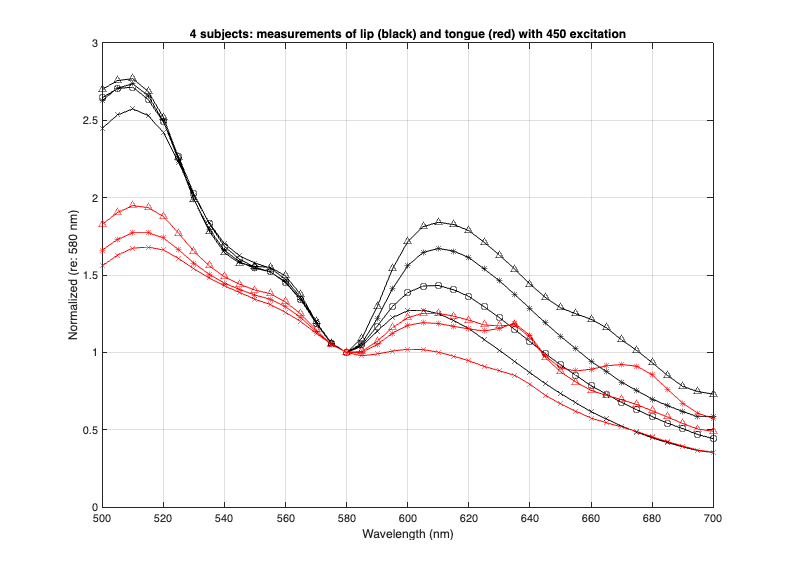

symbols = {'kx-','k*-','k^-','ko-'};
lipFiles450 = ieTableGet(T,'ewave',450,'substrate','lip','elevel',870,'return','files');
data = oeReadFiles(lipFiles450,'waves',waves,'normalized wave',nWave);
ieNewGraphWin;
for ii= 1:numel(lipFiles450)
    plot(waves,data(:,ii),symbols{ii}); hold on; 
    set(gca,'yscale',yScale);
end

symbols = {'rx-','r*-','r^-','ro-'};
tongueFiles450 = ieTableGet(T,'ewave',450,'substrate','tongue','elevel',870,'return','files');
% Collected on the same day as above.
data = oeReadFiles(tongueFiles450,'waves',waves,'normalized wave',nWave);

for ii= 1:numel(tongueFiles450)
    plot(waves,data(:,ii),symbols{ii}); hold on;
end

grid on;
xlabel('Wavelength (nm)')
if isempty(nWave), ylabel('Energy (watts/sr/nm/m^2)');
else, ylabel(sprintf('Normalized (re: %d nm)',nWave));
end
title('4 subjects: measurements of lip (black) and tongue (red) with 450 excitation');